# **Matlab homework (Lab 2)**

clear; close all;
% insert your names and IDs here
Name{1} = 'Laura Guàrdia Vela';
NIA{1} = 240239;
Name{2} = 'Adrià Julià Parada';
NIA{2} = 242195;

D_aux=readtable('DataLab2.csv'); % obrim el fitxer .csv

%emmagatzemem les dades en una matriu auxiliar
x1=D_aux{:,1};
exp_x2=D_aux{:,2};
y=D_aux{:,3};

n = 183;
x2 = ones(n,1);
for i = 1:n
    x2(i) = log(exp_x2(i)); % Reescalem les dades aplicant el logaritme a totes elles perquè ens quedi de forma lineal 
end

%creem la matriu amb les dades que usarem 
D = [x1, x2]; 
D = [D, y];

save('datafile.mat','x1','x2','y') %guardem les dades en un fitxer .mat


%% load file from .mat
load datafile.mat % you can edit here if your datafile has a different name, but do not add path to the file (otherwise it does not work on a different computer)

# QUESTION 2

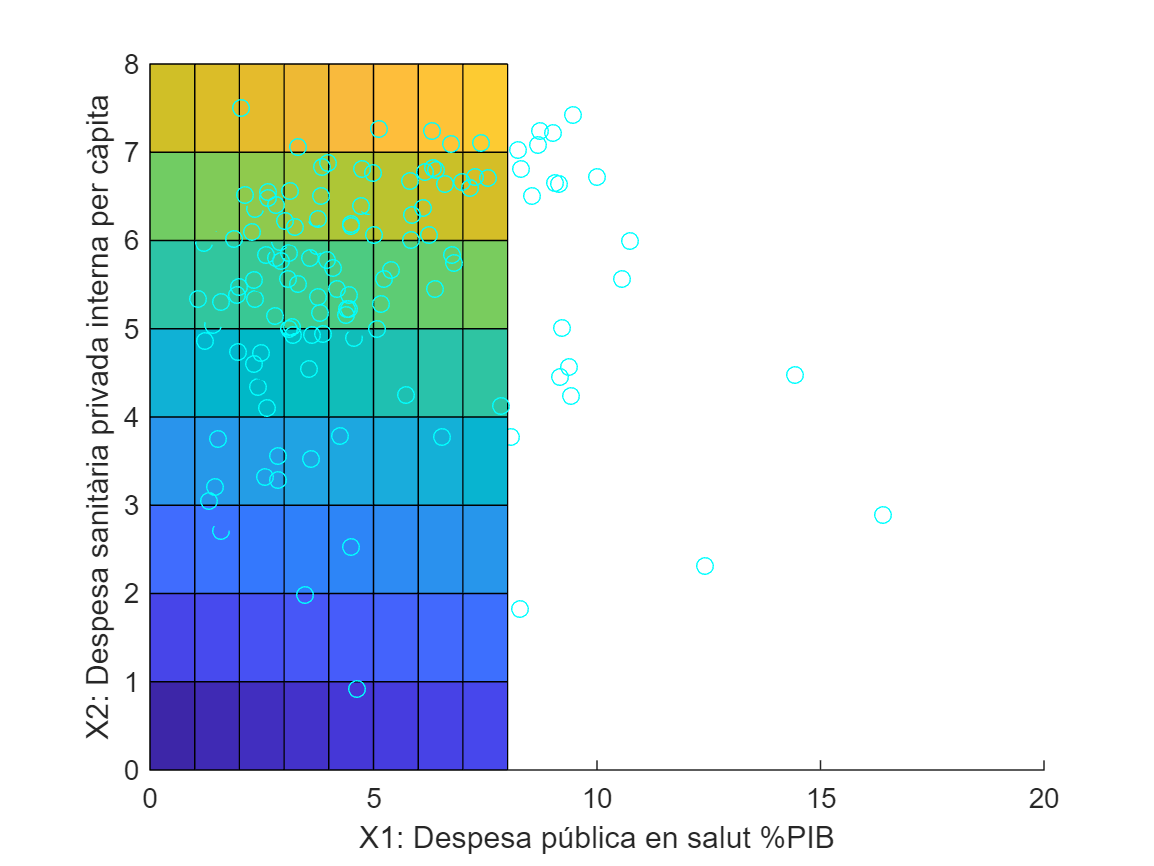

% Enter code for question 2 here

% Càlcul de les b
% (Xt·X)b = Xt·y -> b = (Xt·X)(^-1)Xt·y

% calculem Xt·X
c_ones = ones(n,1);
X = [c_ones, x1];
X = [X, x2];

Xt = transpose(X);
XtX = Xt*X;
inverse_XtX = inv(XtX);

% calculem Xt·y
Xty = Xt*y;
b = inverse_XtX*Xty;

% plot de les dades i del pla de regressió
hold on

xlabel('X1: Despesa pública en salut %PIB')
ylabel('X2: Despesa sanitària privada interna per càpita')
zlabel('Y: Esperança de vida')
scatter3(x1,x2,y,'red');

[a,c] = meshgrid(0:1:8);
z = b(1) + b(2)*a + b(3)*c; 
surf(a,c,z);
hold off

# QUESTION 3

% write your code here code
% Càlcul del coeficient de determinació R^2


y_mitjana = 0;
for i = 1:n
    y_mitjana = y_mitjana + y(i);
end
y_mitjana = y_mitjana/n;

y_barret = X*b;

SS_Reg = 0;
for i = 1:n
    SS_Reg = SS_Reg + (y_barret(i)-y_mitjana)^2;
end

SS_Tot = 0;
for i = 1:n
    SS_Tot = SS_Tot + (y(i)-y_mitjana)^2;
end

R_2 = SS_Reg/SS_Tot

R_2 = 0.5346


% Test F per al model sencer: F ~ F_alfa,k,n-k-1 -> cua dreta
% H0: beta_1 = beta_2 = (...) = beta_k = 0 
% HA: almenys un beta_j != 0

% Càlcul del estadístic F -> F = MS_Reg/MS_Err

k = 2; % graus de llibertat
MS_Reg = SS_Reg/k;

% Càlcul de SS_Err
SS_Err = 0;
for i = 1:n
    SS_Err = SS_Err + (y(i)-y_barret(i))^2;
end
SS_Err;

MS_Err = SS_Err/(n-k-1);

F_estadistic = MS_Reg/MS_Err

F_estadistic = 103.3921


% Càlcul de F a nivell de significació 0,05 per saber els límits de les regions d'acceptació i rebuig de la hipòtesi nul·la

F = finv((1-0.05),k,n-k-1)

F = 3.0461


% Regió d'acceptació de la hipòtesi nul·la: (-infinit , F_alfa,k,n-k-1) ---> Si acceptem H0 hi ha una mala regressió
% Regió de rebuig de la hipòtesi nul·la: [F_alfa,k,n-k-1 , +infinit) ---> Si rebutgem H0 hi ha una bona regressió 
 
if(F_estadistic >= F)
    fprintf("Rebutgem Hipòtesi Nul·la i acceptem Hipòtesi Alternativa");
else
    fprintf("Acceptem Hipòtesi Nul·la i rebutgem Hipòtesi Alternativa");
end

Rebutgem Hipòtesi Nul·la i acceptem Hipòtesi Alternativa


%P value
p = 1 - fcdf(F_estadistic,k,n-k-1)

p = 0

# QUESTION 4

% write your code here
% Test t per a cada pendent beta_j:
% H0: beta_j = 0
% HA: beta_j != 0 

% Càlcul de t a nivell de significació 0,05 per saber els límits de les regions d'acceptació i rebuig de la hipòtesi nul·la
% t = t_alfa/2,n-k-1 (k = graus de llibertat)

t = tinv((1-0.05/2),n-k-1)

t = 1.9732


% Regió d'acceptació de la hipòtesi nul·la: (-t_alfa/2,n-k-1 , t_alfa/2,n-k-1) ---> Si acceptem H0 hi ha una mala regressió 
% Altrament rebutgem la hipòtesi nul·la ---> Si rebutgem H0 hi ha una bona regressió 

% Trobem els dos estadístics de t

% Test t per a b1 (posem b(2) perquè la els arrays comencen per 1, que seria el b(0))
t_estadistic_b1 = b(2)/sqrt(MS_Err * inverse_XtX(1,1))

t_estadistic_b1 = 0.3596


if((t >= t_estadistic_b1) && (-t <= t_estadistic_b1))
    fprintf("Acceptem Hipòtesi Nul·la i rebutgem Hipòtesi Alternativa");
else 
    fprintf("Rebutgem Hipòtesi Nul·la i acceptem Hipòtesi Alternativa");
end

Acceptem Hipòtesi Nul·la i rebutgem Hipòtesi Alternativa


% P value
p1 = 2*(1 - tcdf(t_estadistic_b1,k))

p1 = 0.7536



% Test t per a b2 (posem b(3) perquè la els arrays comencen per 1, que seria el b(0))
t_estadistic_b2 = b(3)/sqrt(MS_Err * inverse_XtX(2,2))

t_estadistic_b2 = 26.9255


if((t >= t_estadistic_b2) && (-t <= t_estadistic_b2))
    fprintf("Acceptem Hipòtesi Nul·la i rebutgem Hipòtesi Alternativa");
else 
    fprintf("Rebutgem Hipòtesi Nul·la i acceptem Hipòtesi Alternativa");
end

Rebutgem Hipòtesi Nul·la i acceptem Hipòtesi Alternativa


% P value
p2 = 2*(1 - tcdf(t_estadistic_b2,k))

p2 = 0.0014